# Design of Notch Filters

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Suppose we need a notch filter to remove the normalized frequency $F_{0}=0.15$. Start with a zero at $z=e^{j2\pi F_{0}$ and a pole at $z=0$.


$$H(F)=\frac{z-e^{j2\pi F_{0}}}{z}=\frac{z-e^{j0.3\pi}}{z}$$


For details, see Section 8.3.2 of the text.

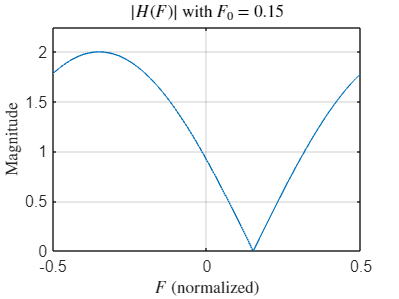

F = [-0.5:0.001:0.5];
Omega = 2*pi*F;
F0 = 0.15;       % Resonant normalized frequency
Omg0 = 2*pi*F0;  % Resonant angular frequency
%r = 0.8;         % Distance of poles from origin
zrs = [exp(j*Omg0)];  % Zeros
pls = [0];            % Poles
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
axis([-0.5,0.5,0,2.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $F_{0}=0.15$');

The magnitude response dips at $F_{0}=0.15$, but it is not sharp enough to be a notch filter.  Let us push the pole at $z=0$ toward the vicinity of the zero.


$$H(z)=\frac{z-e^{j2\pi F_{0}}}{z-r e^{j2\pi F_{0}}}=\frac{z-e^{j0.3\pi}}{z-r e^{j 0.3\pi}}$$


We will try this with $r=0.8$.

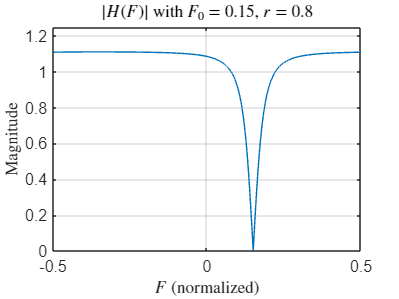

r = 0.8;
pls = [r*exp(j*Omg0)];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
axis([-0.5,0.5,0,1.25]);
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $F_{0}=0.15$, $r=0.8$');

Let us try again, this time with $r=0.9$ which causes the pole to get closer to the zero.

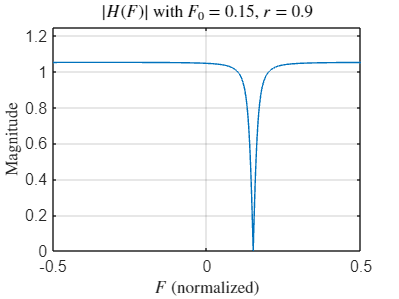

r = 0.9;
pls = [r*exp(j*Omg0)];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
axis([-0.5,0.5,0,1.25]);
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $F_{0}=0.15$, $r=0.9$');

The first-order notch filter has complex coefficients. To avoid them, we can design a second-order notch filter, and have its zeros and poles appear in conjugate pairs.

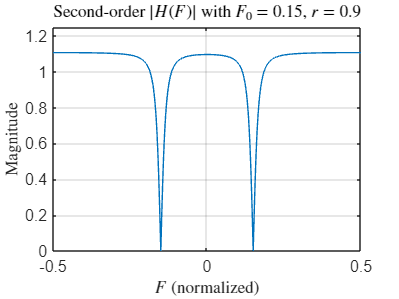

zrs = exp(j*[-1,1]*Omg0);  % Zeros
pls = r*zrs;               % Poles
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
axis([-0.5,0.5,0,1.25]);
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('Second-order $|H(F)|$ with $F_{0}=0.15$, $r=0.9$');

Adjust the gain factor $K$ so that the peak magnitude is unity.  See Eqn. (8.19) in the text.

% Determine the gain factor so that the peak magnitude is 1
peak = ss_freqz(zrs,pls,1,0);
gain = 1/peak

gain = 0.9031

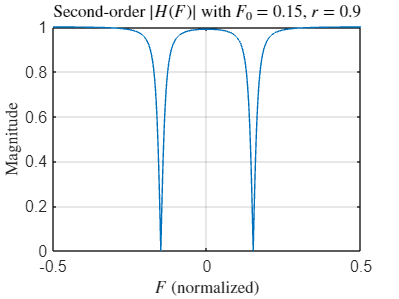

[mag,phs] = ss_freqz(zrs,pls,gain,Omega);
plot(F,mag); grid;
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('Second-order $|H(F)|$ with $F_{0}=0.15$, $r=0.9$');

set(0,'defaultTextInterpreter','tex');